g=9.81;         % m/s^2
% m=0.217;        % kg
% l=0.240;        % m
% tau=1.030;      % s
% zeta=0.0185476; % 
l = 0.0307;
m = 0.1401;
I_cfRod = 0.0000060512;
Ts = 0.01

Ts =    0.010000000000000



theta0 = -0.0591;
dtheta0 = 7.737;

n = 5;
Mag1 = 0.7949;
Magn = 0.17017;
delta = (1/n)*log(Mag1/Magn);
zeta = delta/(sqrt(4*pi()^2 + delta^2));

tau = 0.67749;
omega_n = (2*pi())/(tau*sqrt(1-zeta^2));

format long; I_xx_kgsm = ((m*g*l*tau^2*(1-(zeta^2)))/(4*pi()^2)) - m*l^2 - I_cfRod    % kg.m^2

I_xx_kgsm =      3.512871859049296e-04


I_tot = I_xx_kgsm + m*l^2 + I_cfRod

I_tot =      4.893812349049296e-04


format bank; I_xx_gsmm = I_xx_kgsm*10^9

I_xx_gsmm =      351287.19



format long; c = 2*(I_tot)*zeta*(2*pi())/(tau*sqrt(1-zeta^2))

c =      4.398670391905936e-04


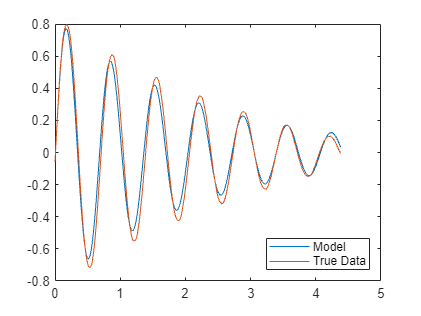


tVec = (0:length(y)-1)*Ts;

handCalc_sys = idgrey('linear_greybox_ss', {m, g, l, I_tot, c}, 'c');

[simout,] = initial(handCalc_sys,[theta0, dtheta0], tVec);

plot(tVec, simout, tVec, y)
legend("Model", "True Data","Location","southeast")